# LAB:  Bearing Fault Monitoring and RUL Estimation

Industrial AI & Automation 2024

**Name**: Jin Kwak/21900031

**Date**: 24.09.24

## Sequence

- Introduction

- Procedure

- Feature Reduction/Selection

- Fault Monitoring and Warning

- RUL estimation

- Discussion

- Conclusion

- Reference

# Introduction

In this LAB, there are two main parts 

**(1) Fault Monitoring ** 

**(2) RUL estimation**

**Download **template matlab code  this lab: [Download here](https://drive.google.com/file/d/1L9iz34MI8v469J30SCM6_38TT7TICXrX/view?usp=share_link)

### Fault Monitoring

- Detect Fault Status

- Display WARNING MESSAGE (OK, Warning, Damaged)

### RUL Estimation

- Estimate RUL similarly to Tutorial codes (CaseStudy 3, 4)

- The End of Life can be assumed when the repair is conducted

**An Example Process**

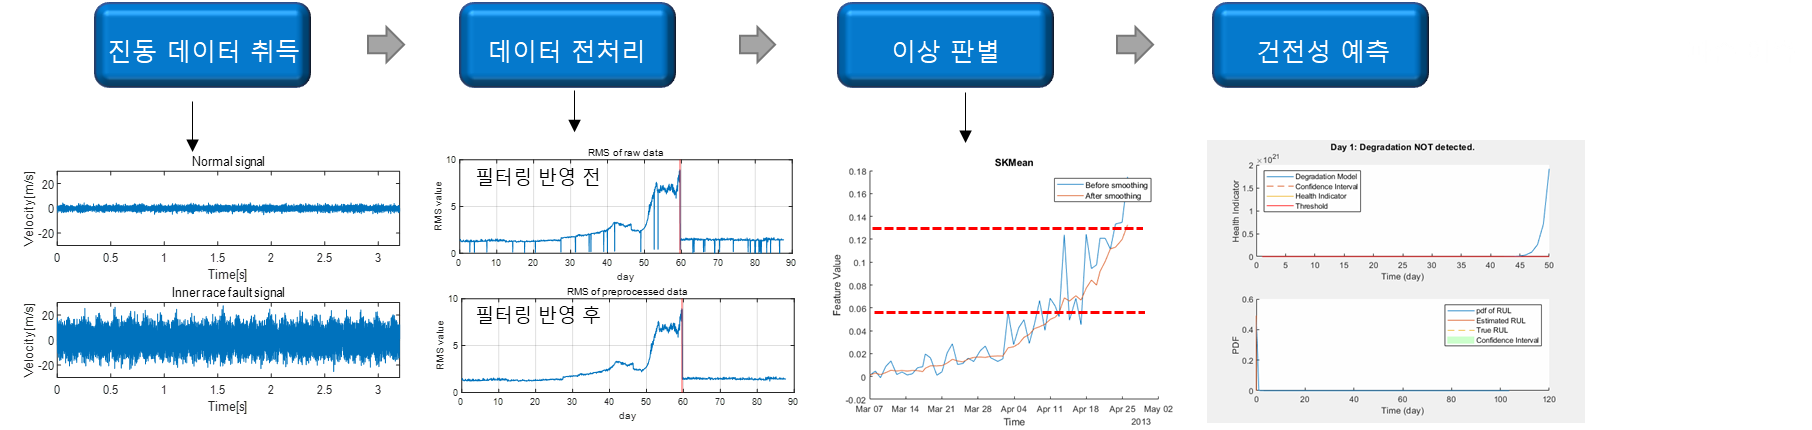

## Dataset

Raw Dataset of Bearing Velocity measured that shows a Bearing Life cycle before the repair is done. Also the velocity measurement after the repair is provided.

**Download** 

bearing dataset for this lab: [Download here](https://drive.google.com/file/d/1L9iz34MI8v469J30SCM6_38TT7TICXrX/view?usp=share_link)

Using the given dataset, develop a simple program for

- Bearing velocity measured 24 times per day

- Each measurement is L=8192 with Fs=2560Hz 

- Measurement for consecutive days until repair is done

**Toolbox used in this lab**

- Signal Processing Toolbox

- System Identification Toolbox

- Predictive Maintenance Toolbox

The dataset given is a time-series data and bearing velocity data is given.

Throughout this lab, the fault is monitored and most importantly, remaining useful life(RUL) is calculated.

To do this, cell datatype is used in order to extract time/frequency domain features.

# Procedure

## Data Preparation

Explain how datasets are prepared 

clc; clear all; close all;
addpath("../../Dataset");
addpath("../../Library");
read_data = 0;

Enumeration

RAW_DATA = 1;     % data{idx,RAW_DATA}
FEATURES = 2;     % data{idx,FEATURES}

N_day_data = 8192;


if ~read_data
    read_data =1;
    load("bearing-vel-fulldata-rul.mat");
    
    numSamples = length(date);
    
    time_stamp = 24     ;%24 data a day
    Fs = 2560           ;%[Hz]
    Ts = 1.0/Fs         ;%[s]
    cnt = 1;
    data{1,1} = [];
    for idx = 1: numSamples
        data{cnt,1} = [data{cnt,1}; bearingFulldata(:,idx)];
        
        if rem(idx,time_stamp) == 0
            cnt = cnt + 1;
            data{cnt,1} = [];
        end
    end
end
num_day = 88;


## Preprocessing and Feature Extraction

**Kurtosis, Standard deviation, peak to peak value extraction(day by day)**

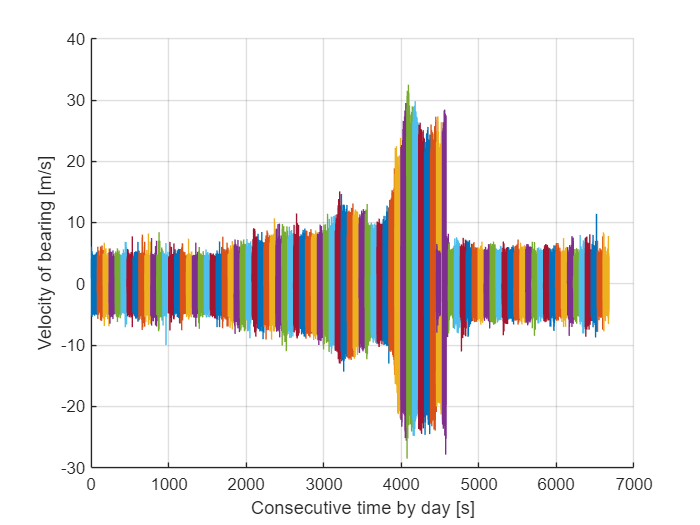

kurto= [];
mean_data = [];
stdv = [];
ppv  = [];
RMS  = [];
mag_STFT =[];
time_STFT=[];
freq_STFT=[];
figure; hold on;
for idx = 1:num_day
    data{idx,2} = get_features(data{idx,1})     ;
    kurto       = [kurto ;data{idx,2}.kt]       ;
    mean_data   = [mean_data  ;data{idx,2}.mean];
    RMS         = [RMS   ;data{idx,2}.rms]      ;
    stdv        = [stdv  ;data{idx,2}.std]      ;
    ppv         = [ppv   ;data{idx,2}.ppv]      ;
    time_idx = (length(data{idx}(:,1))*(idx-1)+1)*Ts:Ts:(idx*length(data{idx}(:,1)))*Ts;
    plot(time_idx, data{idx,1});
end
xlabel('Consecutive time by day [s]'); ylabel('Velocity of bearing [m/s]'); hold on; grid on;

In these graphs, **Bearing signal data** can be compared in the same scale. 

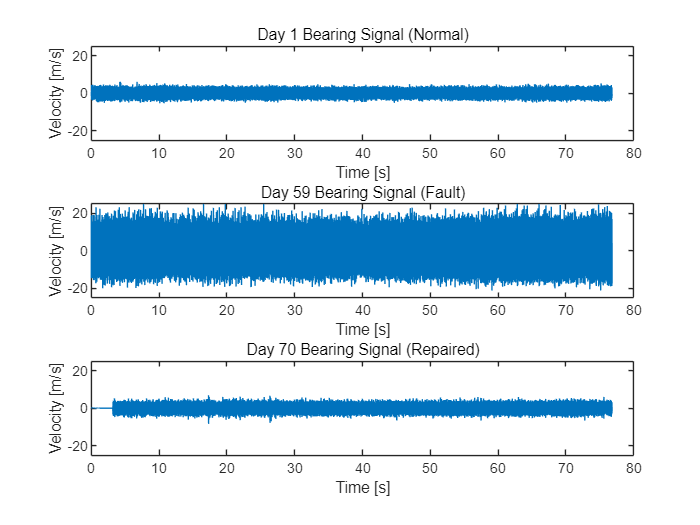

plot1_idx = 1;
plot2_idx = 59;
plot3_idx = 70;

repair_day= 60  ;

figure;
title('Vibration Data of Bearing');
subplot(3,1,1);
time = 0:Ts:(length(data{plot1_idx})-1)*Ts;
plot(time, data{plot1_idx});
ylim([-25 25]);
xlabel('Time [s]');
ylabel('Velocity [m/s]');
title('Day 1 Bearing Signal (Normal)');
subplot(3,1,2);
time = 0:Ts:(length(data{plot2_idx})-1)*Ts;
plot(time, data{plot2_idx});
ylim([-25 25]);
xlabel('Time [s]');
ylabel('Velocity [m/s]');
title('Day 59 Bearing Signal (Fault)');
subplot(3,1,3);
time = 0:Ts:(length(data{plot3_idx})-1)*Ts;
plot(time, data{plot3_idx});
ylim([-25 25]);
xlabel('Time [s]');
ylabel('Velocity [m/s]');
title('Day 70 Bearing Signal (Repaired)');

The 3D-graph shows how the spectrum of FFT varies with Normal/Damaged/Repaired data.

Normal data shows harmonic peaks where damaged data shows chattering of peaks all the time. The repaired dataset shows

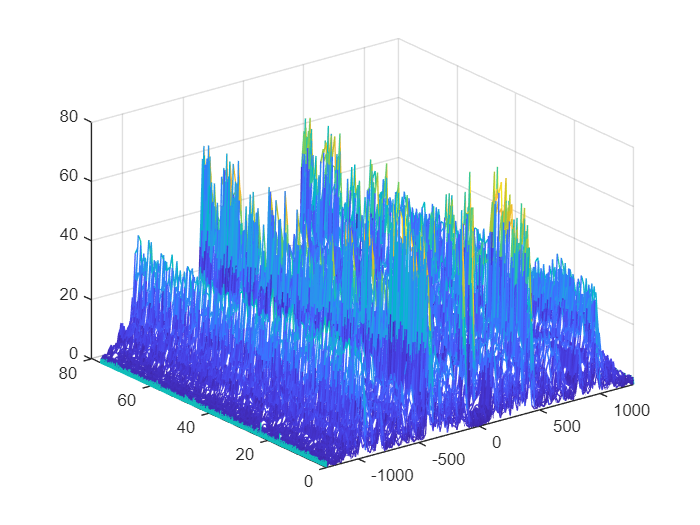

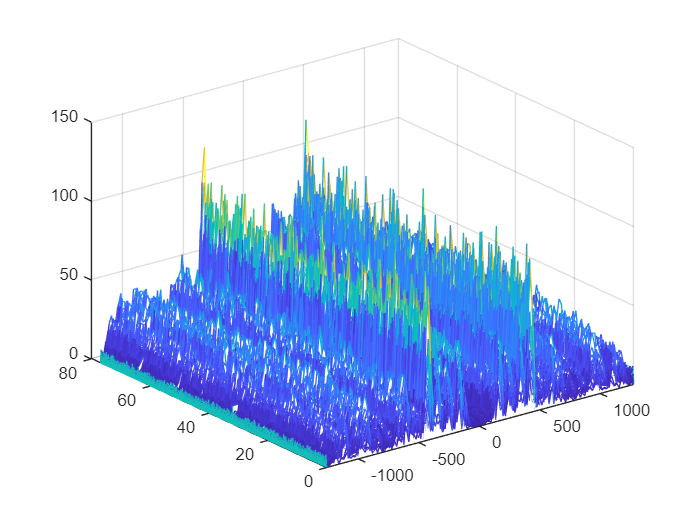

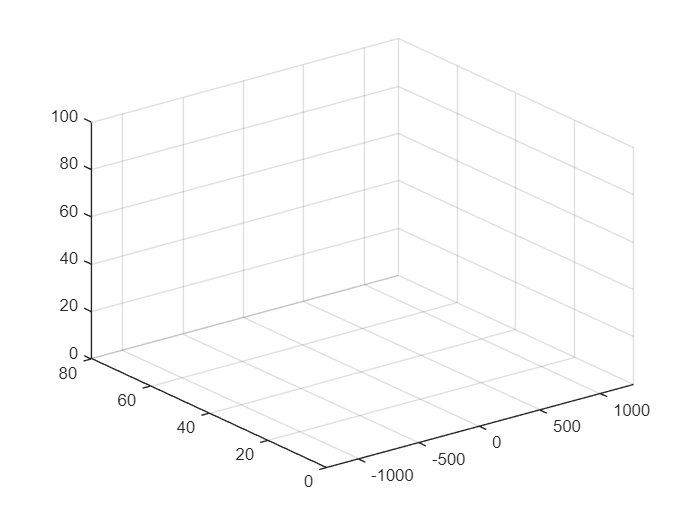

for idx = [1 50 80]
    [S,F,T] = stft(data{idx,1}, 2560);
    figure;
    title('day:',num2str(idx));
    waterfall(F,T,abs(S)')
end

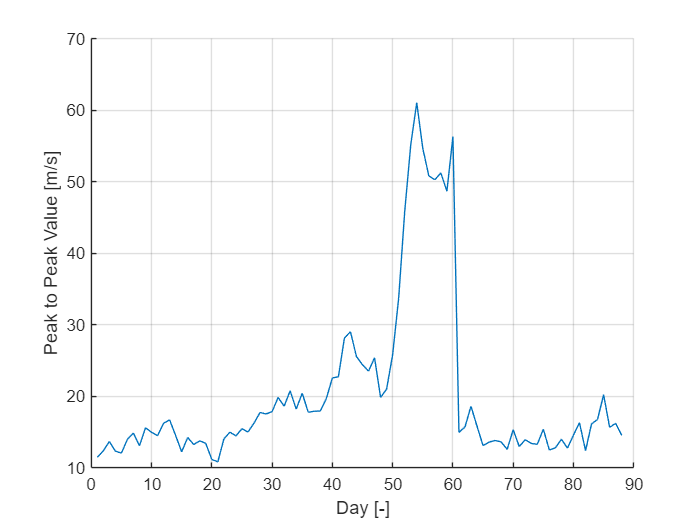

day = 1:num_day;
figure; hold on; grid on;
plot(day,ppv);
xlabel('Day [-]');
ylabel('Peak to Peak Value [m/s]');

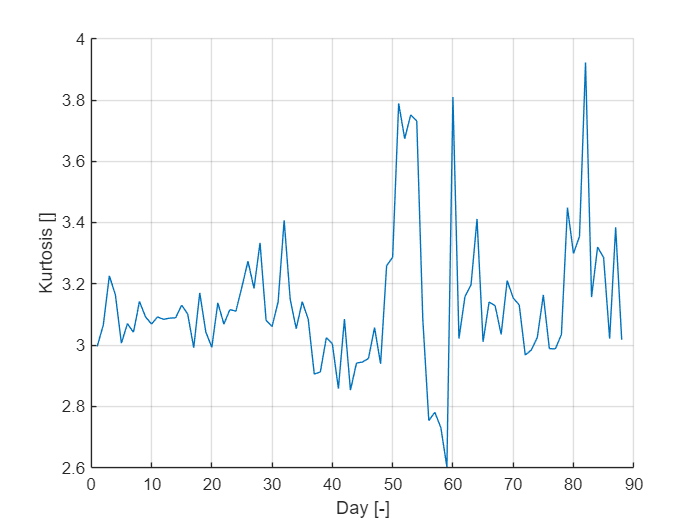

figure; hold on; grid on;
plot(day,kurto);
xlabel('Day [-]');
ylabel('Kurtosis []');

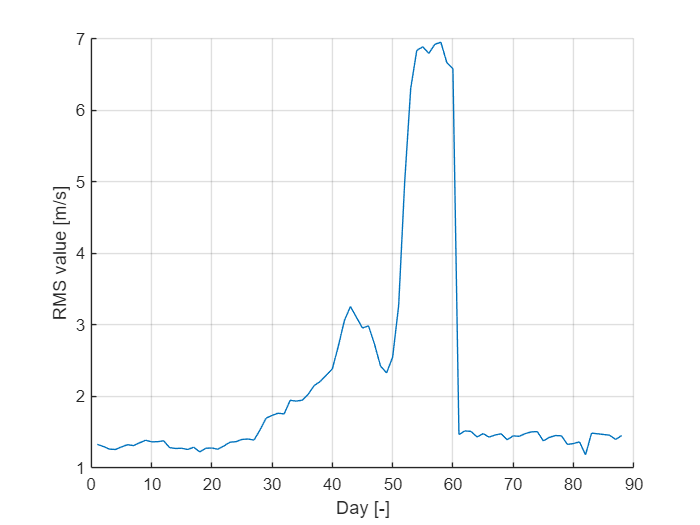

figure; hold on; grid on;
plot(day,RMS);
xlabel('Day [-]');
ylabel('RMS value [m/s]');

disp('Average Kurtosis value of normal bearing dataset');

Average Kurtosis value of normal bearing dataset


average_kurtosis_value = mean(kurto(1:25))

average_kurtosis_value = 3.0909

rms_kurtosis_value = rms(kurto(1:25))

rms_kurtosis_value = 3.0915

disp('Average Peak to Peak value of normal bearing dataset');

Average Peak to Peak value of normal bearing dataset


average_ppv_value = mean(ppv(1:25))

average_ppv_value = 13.7281

rms_ppv_value = rms(ppv(1:25))

rms_ppv_value = 13.8121

% Mean value of rms in normal data and abnormal data
average_rms_value_normal = mean(RMS(1:25))

average_rms_value_normal = 1.3054

average_rms_value_fault  = mean(RMS(35:59))

average_rms_value_fault = 3.8673

- The root-mean squared of Kurtosis, mean value of kurtosis are roughly 0.006 different in other words, in which means that kurtosis of normal data are very likely to be around 3.1.

- Mean values of Root-mean-squared value of normal data and abnormal data differs roughly about 3 times.

- Through this section, Peak to peak value, kurtosis, rms value are observed. 

- The most distinguishable data is rms value 

- distinguishable data

**Spectral Kurtosis**

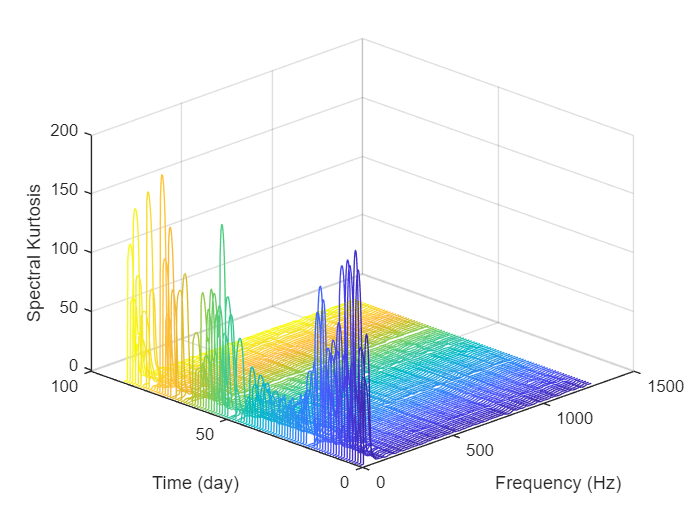

SpectralKurtosis = [];
normal = [];
bad    = [];
% Compute spectral kurtosis with window size = 128
wc = 128;
colors = parula(num_day);

figure; hold on;
for idx = 1:num_day
    % Get vibration signal and measurement date
    vib_data = data{idx,RAW_DATA};
    [SK, F] = pkurtosis(vib_data, Fs, wc);
    data{idx,FEATURES}.SKmean = mean(SK);
    data{idx,FEATURES}.SKstd  = std(SK);
    data{idx,FEATURES}.SKskew = skewness(SK);
    data{idx,FEATURES}.SKkurt = kurtosis(SK);
    SpectralKurtosis = [SpectralKurtosis;data{idx,FEATURES}.SKmean data{idx,FEATURES}.SKstd  data{idx,FEATURES}.SKskew data{idx,FEATURES}.SKkurt];
    plot3(F, day(idx)*ones(size(F)), SK, 'Color', colors(idx, :));
    if idx == 88
        break;
    elseif idx< 25 || (idx>60 && idx <88)
        normal = [normal data{idx,RAW_DATA}];
    else
        bad    = [bad data{idx,RAW_DATA}];
    end
end
normal=[normal [data{88,RAW_DATA}; zeros(length(data{87,RAW_DATA})-length(data{88,RAW_DATA}),1)]];
hold off
xlabel('Frequency (Hz)')
ylabel('Time (day)')
zlabel('Spectral Kurtosis')
grid on; view(-45, 30);

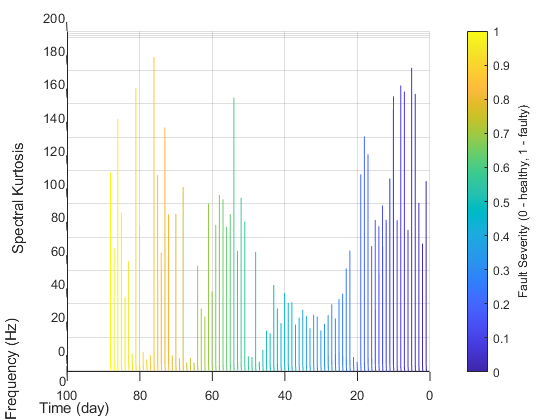

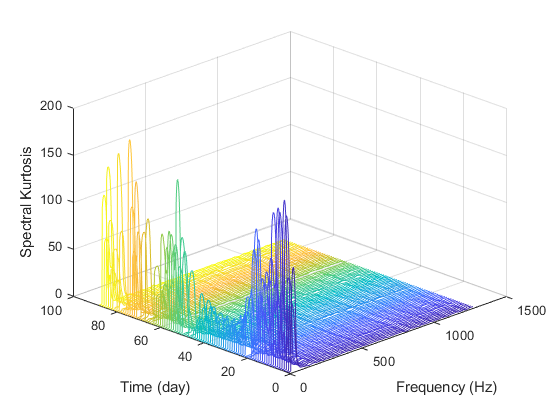

Plot SKmean

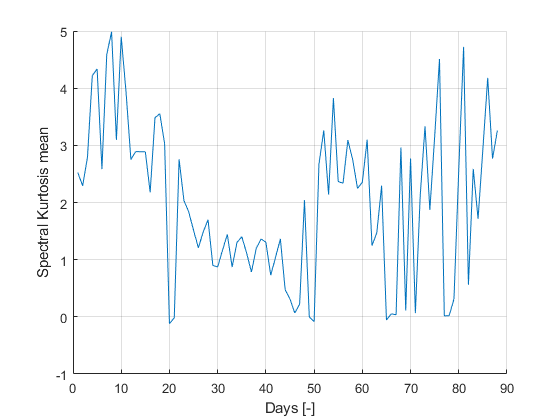

%Plot
SK_MEAN = 1;
SK_STD  = 2;
SK_SKEW = 3;
SK_KURT = 4;
figure; hold on; grid on;
plot(day, SpectralKurtosis(:,SK_MEAN));
xlabel('Days [-]'); ylabel("Spectral Kurtosis mean");

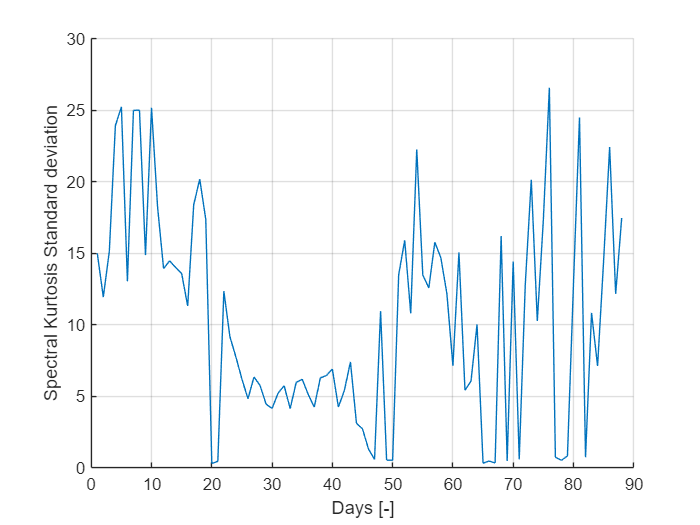

figure; hold on; grid on;
plot(day, SpectralKurtosis(:,SK_STD));
xlabel('Days [-]'); ylabel("Spectral Kurtosis Standard deviation");

Spectral Kurtosis mean/ skewness does not show very distinct variation with normal/fault data

The features are tabulated. 

Rows     : Days

Columns: Features

data_in_table = cell2table(data);

The columns are updated until the repair day(Which is assumed 60th day).

data_in_table = data_in_table(1:repair_day,:)

data_in_table = 60×16 table
    fft_max_idx      IF        SF        CF        MF       RMS        SRA        AAV        energy      PEAK    PEAK2PEAK      SKEW       KURTOSIS    SK_STD    SK_MEAN    SK_KURTOSIS
    ___________    ______    ______    ______    ______    ______    _______    _______    __________    ____    _________    _________    ________    ______    _______    ___________

         31596     5.7178    1.2536    4.5612    6.7514    1.3242    0.89463     1.0563    3.4477e+05    6.04      11.44      -0.051906     2.9957     14.988    2.5236       39.206   
         32055     6.0796    1.2569    4.8372     7.187    1.2941    0.87102     1.0297    3.2928e+05    6.26      12.33      -0.051787     3.0656     11.926    2.2908       28.088   
         32049     6.8109    1.2804    5.3191    8.2396    1.2577    0.81193    0.98225    3.1101e+05    6.69      13.64      -0.064156     3.2259     15.134    2.7905       32.507   
    1.6455e+05     5.8755    1.2796    4.5916    7.

window_size = 5;
data_in_table_MAF5 = varfun(@(x) movmean(x, [window_size 0]), data_in_table); %smoothing
data_in_table_MAF5.Properties.VariableNames = data_in_table.Properties.VariableNames;

Smoothing the dataset may give soft curve shape and may be more fit to the degradation curve.

Yet the moving average filter acts as a phase delay and may affect the trendability of the dataset. Therefore, the window size 5 is selected. Maximum time(phase) delay of the system is 5 days because warning status may be up to 20~30 days until the next status(Fault).

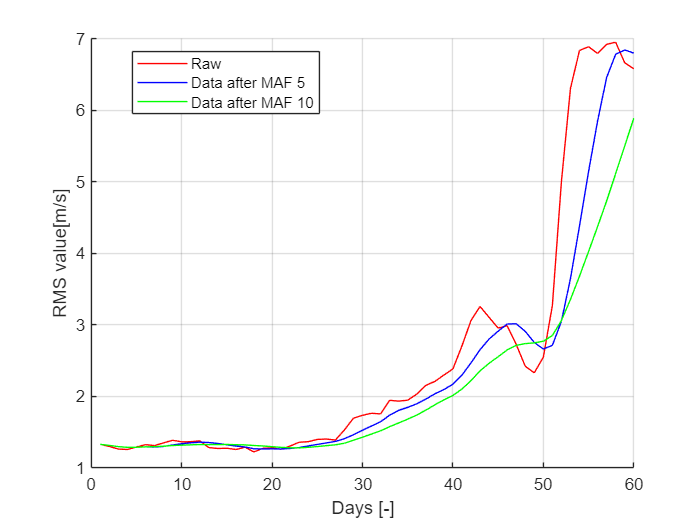

data_in_table_MAF10 = varfun(@(x) movmean(x, [10 0]), data_in_table); %smoothing
data_in_table_MAF10.Properties.VariableNames = data_in_table.Properties.VariableNames;

figure; hold on; grid on;
xlabel('Days [-]'); ylabel('RMS value[m/s]');
plot(data_in_table.RMS,'r-');
plot(data_in_table_MAF5.RMS,'b-'); 
plot(data_in_table_MAF10.RMS,'g-'); 
legend('Raw','Data after MAF 5','Data after MAF 10'); legend('Location','best');

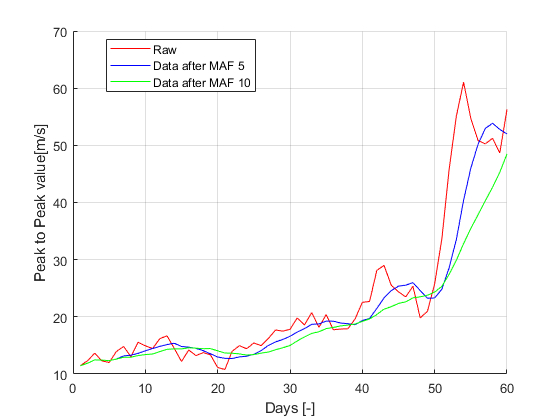

figure; hold on; grid on;
xlabel('Days [-]'); ylabel('Peak to Peak value[m/s]');
plot(data_in_table.PEAK2PEAK,'r-');
plot(data_in_table_MAF5.PEAK2PEAK,'b-'); 
plot(data_in_table_MAF10.PEAK2PEAK,'g-'); 
legend('Raw','Data after MAF 5','Data after MAF 10'); legend('Location','best');

# Feature Reduction/Selection

Energy is the most relevent monotonicity feature.

Energy  $\rightarrow$ AAV(Average Absolute Value) $\rightarrow$SRA(Square Root Average) $\rightarrow$Peak and Peak to peak features

This shows that the phenomenons caused by fault of a bearing may affect the amplitude the most as the important features are all related to the amplitude(e.g. $Energy = \Sigma x^2(t)$).

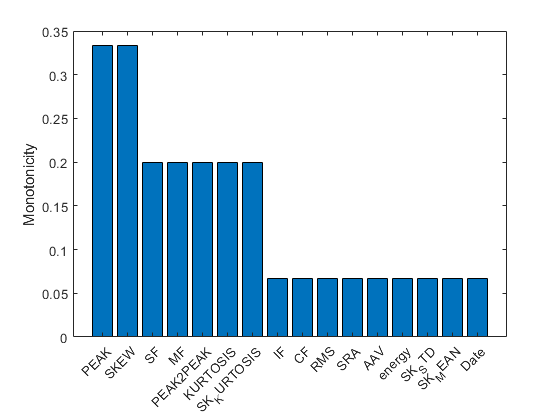

break_point = 45;
feature_monotonicity = monotonicity(data_in_table_MAF5(break_point:end,:), 'WindowSize', 0);
names   = string(feature_monotonicity.Properties.VariableNames);
important_feature = table2array(feature_monotonicity);
helperSortedBarPlot(feature_monotonicity,'Monotonicity');

confidence_level = 0.15;
train_selected = data_in_table_MAF5(:, feature_monotonicity{:,:}>=confidence_level)

train_selected = 60×7 table
      IF        CF        energy       PEAK     PEAK2PEAK      SKEW       SK_MEAN
    ______    ______    __________    ______    _________    _________    _______

    5.7178    4.5612    3.4477e+05      6.04      11.44      -0.051906    2.5236 
    5.8987    4.6992    3.3702e+05      6.15     11.885      -0.051847    2.4072 
    6.2028    4.9058    3.2835e+05      6.33      12.47       -0.05595     2.535 
     6.121    4.8273    3.2334e+05     6.185     12.425      -0.057065    2.9558 
    6.0226    4.7585     3.238e+05     6.102     12.342      -0.056219    3.2321 
    6.1049    4.8298    3.2683e+05     6.225      12.61      -0.056156    3.1242 
    6.3904    5.0554    3.2534e+05    6.5067     13.172      -0.056888    3.4683 
    6.4597    5.0958     3.297e+05    6.6017      13.29      -0.056287    3.9176 
    6.5408     5.177    3.4038e+05    6.8233      13.61      -0.053264    3.9685 
    6.8265    5.4182    3.4956e+05    7.2333      14.05      -0.04933

feature_selected = data_in_table_MAF5(:, feature_monotonicity{:,:}>=confidence_level);

To achieve PCA, **Normalization **is applied

mean_train = mean(train_selected{:,:})

mean_train = 	1.0e+06 *

    0.0000    0.0000    1.5293    0.0000    0.0000   -0.0000    0.0000


std_train  = std(train_selected{:,:})

std_train = 	1.0e+06 *

    0.0000    0.0000    2.3571    0.0000    0.0000    0.0000    0.0000


train_norm = (train_selected{:,:}- mean_train)./std_train;
coeff_pca  = pca(train_norm)

coeff_pca =    -0.3379    0.4891   -0.3755   -0.1178    0.0685   -0.6974    0.0252
   -0.3555    0.4610   -0.3431   -0.1982   -0.0595    0.7073   -0.0176
    0.4326    0.2527    0.1360   -0.4779    0.7071    0.0440   -0.0146
    0.4457    0.2272   -0.0565   -0.1613   -0.4361   -0.0154    0.7281
    0.4461    0.2211   -0.0639   -0.2011   -0.4856   -0.0651   -0.6838
    0.4008    0.2213   -0.4156    0.7398    0.2500    0.0831   -0.0312
   -0.1187    0.5787    0.7367    0.3234   -0.0580    0.0059   -0.0137


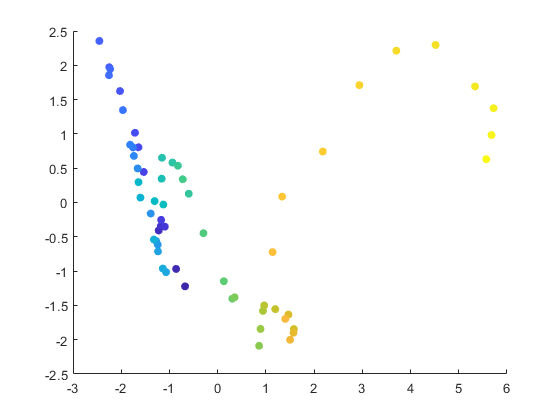

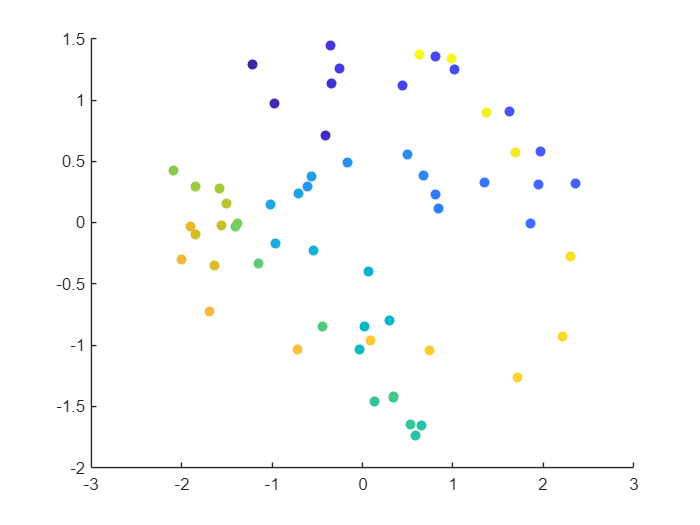

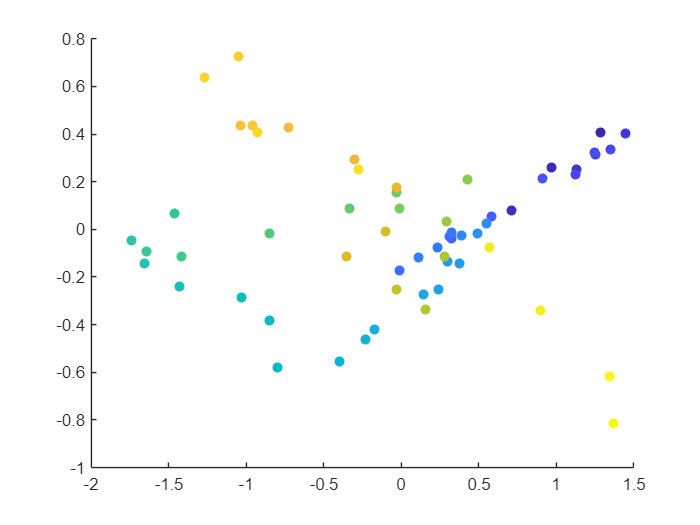

num_pca = length(coeff_pca(:,1));
for idx = 1:num_pca
    PCA(:,idx) = (feature_selected{:,:} - mean_train) ./ std_train * coeff_pca(:, idx);
end
for idx = 1:num_pca-1
    figure;
    scatter(PCA(:,idx), PCA(:,idx+1), [], 1:repair_day, 'filled');
    if idx >2
        break;
    end
end

After the trends of PCA data, PCA 1 is chosen.

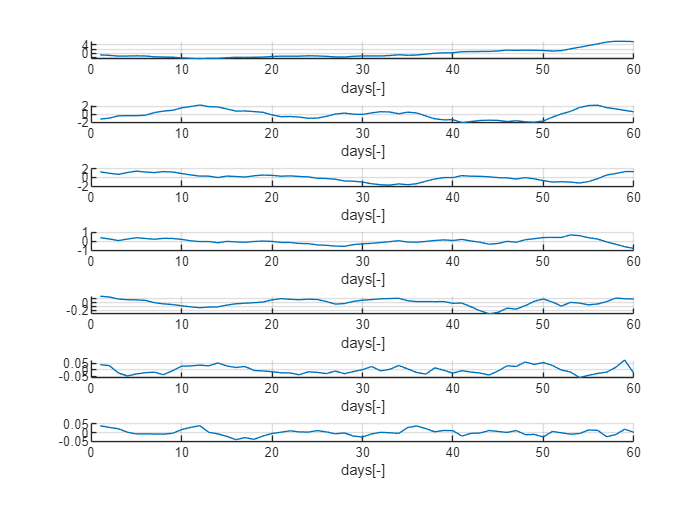

figure;
for idx =1:num_pca
    subplot(num_pca,1,idx); hold on; grid on ;
    plot(PCA(:,idx)); xlabel('days[-]');
end

# Fault Monitoring and Warning

After the PCA graph above, PCA1 is chosen as the health indicator. PCA 1 data has the most large scale of value.

Using this graph, warning threshold, damaged threshold are chosen.

From day 30, the value reached -1 and this implies that the system is now in aware.

Around day 53, the health indicator is rapidly increasing.

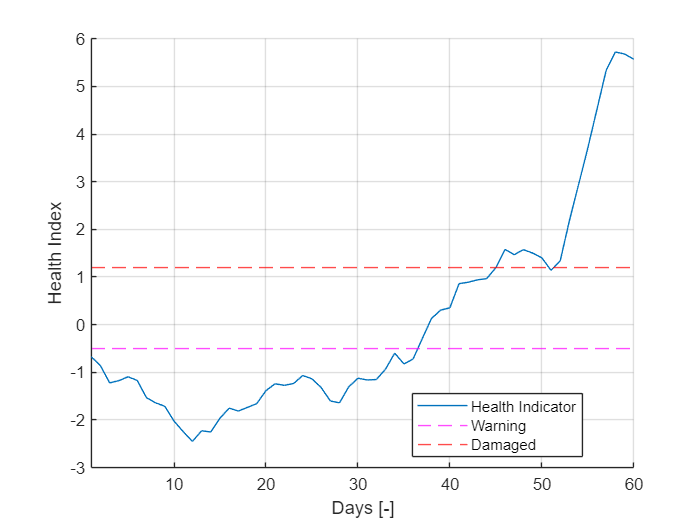

health_indicator = PCA(:,1);
days = 1:repair_day;
figure; hold on; grid on;
plot(days, health_indicator,'DisplayName','Health Indicator'); xlabel('Days [-]'); ylabel('Health Index');xlim([1 repair_day]);
yline(-0.5,'m--','DisplayName','Warning'); yline(1.2,'r--','DisplayName','Damaged'); legend('Location','best');

After monotonicity, trendability and prognosability is tested. 

They do not show distinct features and therefore, **withdrawed**.

% feature_trendability = trendability(data_in_table_MAF5);
% names   = string(feature_trendability.Properties.VariableNames);
% important_feature_trend = table2array(feature_trendability);
% figure; bar(categorical(names),important_feature_trend); 
% xlabel('Features');ylabel('Trendability level');

# RUL Estimation

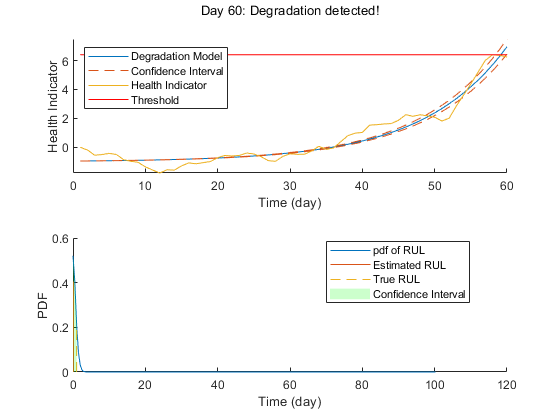

healthIndicator = health_indicator - health_indicator(1);
% healthIndicator = healthIndicator(1:60);
threshold_HI    = max(healthIndicator);

mdl = exponentialDegradationModel(...
    'Theta', 1, ...
    'ThetaVariance', 1e6, ...
    'Beta', 1, ...
    'BetaVariance', 1e6, ...
    'Phi', -1, ...
    'NoiseVariance', (0.1*threshold_HI/(threshold_HI + 1))^2, ...
    'SlopeDetectionLevel', 0.05);

total_day = 88;
estRULs   = zeros(repair_day,1);
trueRULs  = zeros(repair_day,1);
CI_RULs   = zeros(repair_day,2);
pdfRULs   = cell (repair_day,1);


% Create figures and axes for plot updating
figure
ax1 = subplot(2, 1, 1);
ax2 = subplot(2, 1, 2);
timeUnit = 'day';
for currentDay = 1:repair_day
    
    % Update model parameter posterior distribution
    update(mdl, [currentDay healthIndicator(currentDay)]);
    
    % Predict Remaining Useful Life
    [estRUL, CIRUL, pdfRUL] = predictRUL(mdl, ...
                                         [currentDay healthIndicator(currentDay)], ...
                                         threshold_HI);
    trueRUL = repair_day - currentDay + 1;
    
    % Updating RUL distribution plot
    helperPlotTrend(ax1, currentDay, healthIndicator, mdl, threshold_HI, timeUnit);
    helperPlotRUL(ax2, trueRUL, estRUL, CIRUL, pdfRUL, timeUnit)
    
    % Keep prediction results
    estRULs(currentDay) = estRUL;
    trueRULs(currentDay) = trueRUL;
    CIRULs(currentDay, :) = CIRUL;
    pdfRULs{currentDay} = pdfRUL;
    pause(0.1);
    legend('Location','best')
end 

Before the break point, the health indicator decreases and this might not satisfy the exponential degradation model, if this happens, this implies the fact that the data is healthy and clean.

# Discussion

The red graph is the increase in prediction accuracy through learning. The data is compared as if the prediction matches with true RUL.

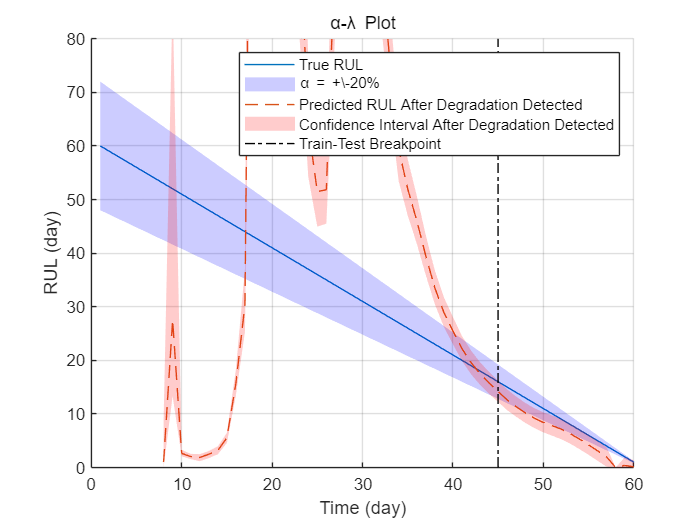

% Performance Analysis
data_in_table_MAF5.Date = (1:repair_day)';

alpha = 0.2;
detectTime = mdl.SlopeDetectionInstant;
prob = helperAlphaLambdaPlot(alpha, trueRULs, estRULs, CIRULs, ...
    pdfRULs, detectTime, break_point, timeUnit);
title('\alpha-\lambda Plot')

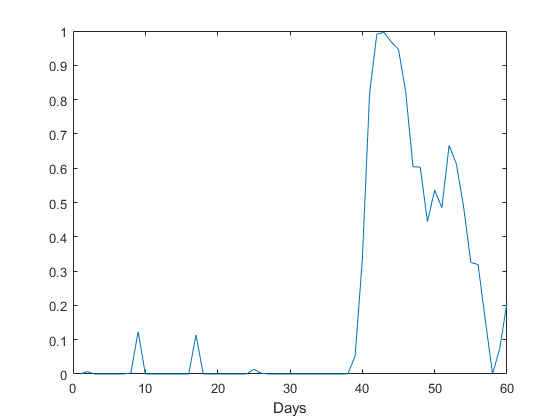

figure; plot(prob); xlabel('Days');

# Conclusion

This Lab deals with Health Monitoring approach for bearing data. Basic time features of the time-series dataset are extracted at the **Procedure.** Important features are selected. PCA is used to replace the whole features for health indicator. The health indicator is selected as it shows dramatic degradation from day 30 upto replacement. For conservative approach to estimate the degradation, break point is assumed to be day 45.

The threshold levels of **warning** and **damaged **are -0.5 and 1.2 respectively for the selected health indicator. -0.5 is as the health indicator tends to increase at the level of 0.5. 1.2 value is selected as the degradation accelerates to the maximum value.

As the $\alpha$-$\lambda$ does not match with the true RUL until about day 35, the RUL shows that the data is absolutely normal at the first half. The predicted RUL starts to match from day 40.

Because of the wear of industrial equipment, the degradation model may look exponential or linear. At this point, the degradation model is exponential where the bearing starts to crack more rapidly as it cracks.

**Caution:** The data of each day is extracted hour by hour, but this data is **concatenated **as a day, this might **affect the frequency/time features**. The author assumed that can be ignored and treated as random noise. To prevent this happening, try averaging the total day dataset as there are 24 dataset within a day which is enough and using **Central Limit Theorem**, the random noises can be removed. This may bring better effect to the result.

**Functions**

function xfeature = get_features(x)
% This is based on the function timeFeatures() 
% Input: Raw Data (Time-series)
% Output: Struct type
% |
% |---Time features(e.g. RMS, peak2peak, kurtosis)
% |---Frequency features(e.g. FFT, rmsf)
N = length(x);
xfeature.mean=mean(x);
xfeature.std=std(x);

xfeature.rms      =sqrt(sum(x.^2)/N);
xfeature.sra      =(sum(sqrt(abs(x)))/N)^2;
xfeature.aav      =sum(abs(x))/N;
xfeature.energy   =sum(x.^2);
xfeature.peak     =max(x);
xfeature.ppv      =peak2peak(x);
xfeature.if       =xfeature.peak/xfeature.aav;
xfeature.sf       =xfeature.rms/xfeature.aav;
xfeature.cf       =xfeature.peak/xfeature.rms;
xfeature.mf       =xfeature.peak/xfeature.sra;
xfeature.sk       =skewness(x);
xfeature.kt       =kurtosis(x);
p1 = fft(x);
p1(2:end-1)= 2.0 * p1(2:end-1); 
xfeature.fft = p1;

xfeature.rmsf= sqrt(1/N *sum(xfeature.fft.^2));
end

function data_table = cell2table(data)
% Every data is grouped by a cell, but now they are collected together in
% terms of Time-Series
    rms_data   = [];    sra_data   = [];    aav_data   = [];    energy_data= [];
    peak_data  = [];    ppv_data   = [];    if_data    = [];    sf_data    = [];
    cf_data    = [];    mf_data    = [];    sk_data    = [];    kurto_data = [];
    SKmean_data= [];    SK_std_data= [];    SK_kt_data = [];    fft_max_idx= [];
    
    
    days = 1:88;
    
    data_table = table;
    for idx = days
        rms_data   = [rms_data   ;data{idx,2}.rms   ];
        sra_data   = [sra_data   ;data{idx,2}.sra   ];
        aav_data   = [aav_data   ;data{idx,2}.aav   ];
        energy_data= [energy_data;data{idx,2}.energy];
        peak_data  = [peak_data  ;data{idx,2}.peak  ];
        ppv_data   = [ppv_data   ;data{idx,2}.ppv   ];
        if_data    = [if_data    ;data{idx,2}.if    ];
        sf_data    = [sf_data    ;data{idx,2}.sf    ];
        cf_data    = [cf_data    ;data{idx,2}.cf    ];
        mf_data    = [mf_data    ;data{idx,2}.mf    ];
        sk_data    = [sk_data    ;data{idx,2}.sk    ];
        kurto_data = [kurto_data ;data{idx,2}.kt    ];
        SK_std_data= [SK_std_data;data{idx,2}.SKstd ];
        SK_kt_data = [SK_kt_data ;data{idx,2}.SKkurt];
        SKmean_data= [SKmean_data;data{idx,2}.SKmean];
        fft_max_idx= [fft_max_idx;find(data{idx,2}.fft==max(data{idx,2}.fft))];
    end
    data_table.fft_max_idx = fft_max_idx;
    data_table.IF          = if_data    ;
    data_table.SF          = sf_data    ;
    data_table.CF          = cf_data    ;
    data_table.MF          = mf_data    ;
    data_table.RMS         = rms_data   ;
    data_table.SRA         = sra_data   ;
    data_table.AAV         = aav_data   ;
    data_table.energy      = energy_data;
    data_table.PEAK        = peak_data  ;
    data_table.PEAK2PEAK   = ppv_data   ;
    data_table.SKEW        = sk_data    ;
    data_table.KURTOSIS    = kurto_data ;
    data_table.SK_STD      = SK_std_data;
    data_table.SK_MEAN     = SKmean_data;
    data_table.SK_KURTOSIS = SK_kt_data ;

end

# Reference

[1][ Github](https://github.com/ykkimhgu/HGU_IAIA)

[2] Rauber, T. W., de Assis Boldt, F., & Varejao, F. M. (2014). Heterogeneous feature models and feature selection applied to bearing fault diagnosis. *IEEE Transactions on Industrial Electronics*, *62*(1), 637-646.